close all
clear
addpath(genpath ('F:\kurser\master\tsbb09\lab 4\IRsensors\'))

## Part 1

**Q1**: Before you come to the exercise: What are the numerical values of c, h, and k, in Planck’s radiation law? Give them in SI-units 

c = 2.997 924 58 * 10^8 m/s

h=  6.626 0688 * 10^-34 Js

k = 1.380 650 * 10^-23 J/K

You need to give the values for these constants in the script. Check that this is done. You also need to specify lambda1, lambda2, and n = the number of terms in the approximation of (4). One of the sensors you will look at in part 3 has 1 = 3.5 µm and 2 = 5 µm. Finally, you need to specify for which temperatures the integrated emittance is computed and plotted. Start with the range 1 to 1000 K. Choose a suitable n and run part1script to compute and plot the integrated emittance as a function of temperature. 

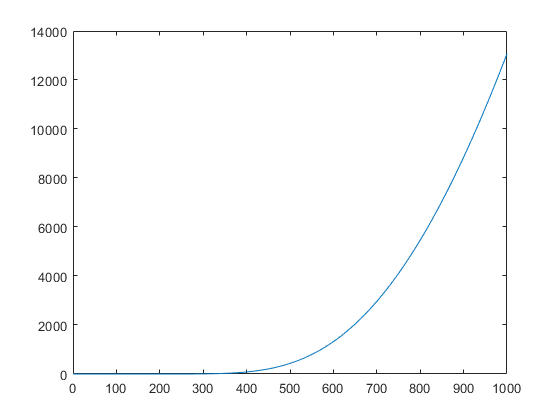

part1script

**Q2**: What does the function look like? Is it linear, or what?

It is exponential.

At some configuration this sensor can detect a maximum in-band irradiance of 40 W/m2 , and becomes saturated for intensities above that. 

**Q3**: Which temperature does this intensity correspond to?

thresh = 40;
I = (Intensity>thresh);
[~, col] = find(I);
disp('Temperature in Kelvin')

Temperature in Kelvin


col(1)

ans = 368

In some IR-sensors, the intensity measurement at a pixel can be done over a relative large wavelength range, but often it is limited by an optical filter in front of the sensor, a filter that defines 1 and 2. 

**Q4**: How can you change the upper or lower wavelength limits to increase the temperature range of this sensor?

By widening the wavelength limits the temperature range will increase so make the upper wavelength higher and lower wavelength smaller.

## Part 3

load ('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor1 Multispectral\Refdata1.mat');
load ('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor1 Multispectral\Refdata2.mat');
load ('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor1 Multispectral\Refdata3.mat');
load ('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor1 Multispectral\Scenedata.mat');

### A. Plotting the sensor data 

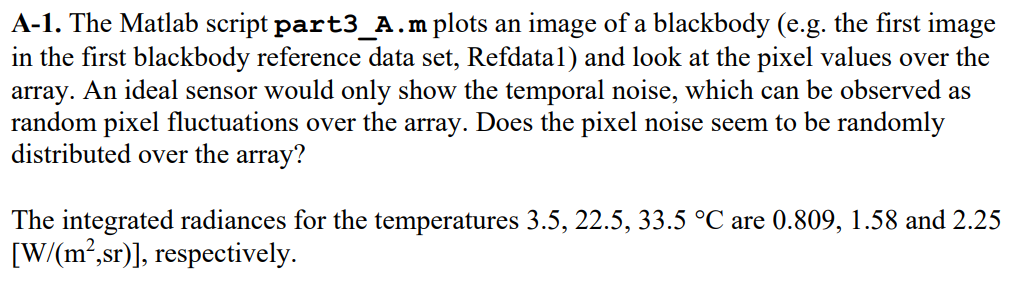    

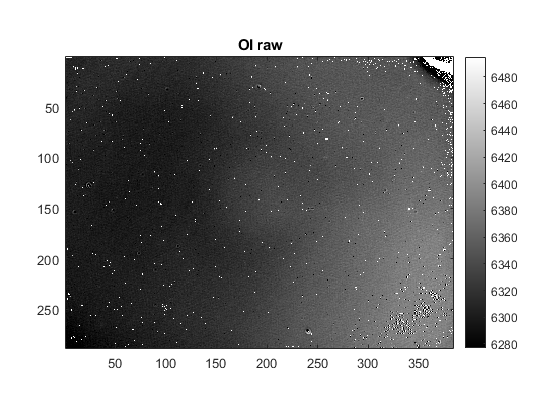

%A-1
OI_raw=Refdata1(:,:,1);
low_high=stretchlim(OI_raw/16383);
figure(1)
imagesc(OI_raw,[low_high(1) low_high(2)]*16383);
axis image; colormap gray;title('OI raw')
colorbar;

clear part low_high 

The noise does not seem to be random

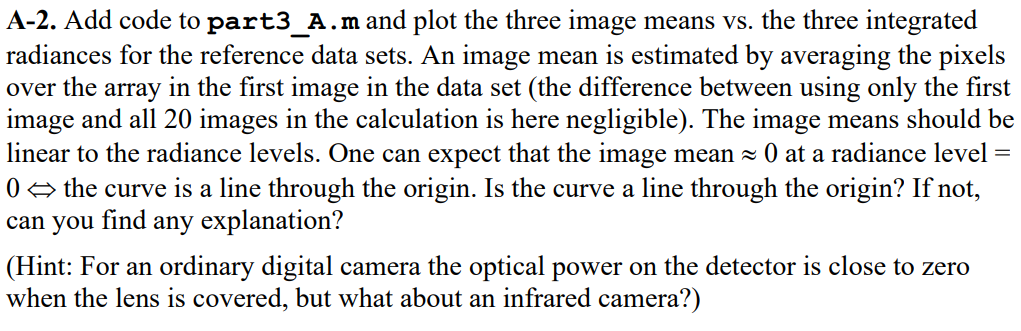

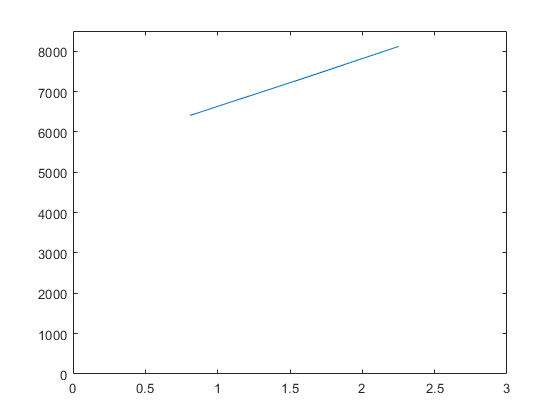

m1 = mean2(Refdata1(:,:,1));
m2 = mean2(Refdata2(:,:,1));
m3 = mean2(Refdata3(:,:,1));
m123 = [m1 m2 m3];
plot([0.809,1.58,2.25],m123)
xlim([0,3])
ylim([0,8500])

Linear but not crossing 0. Thermal offset from camera warmth

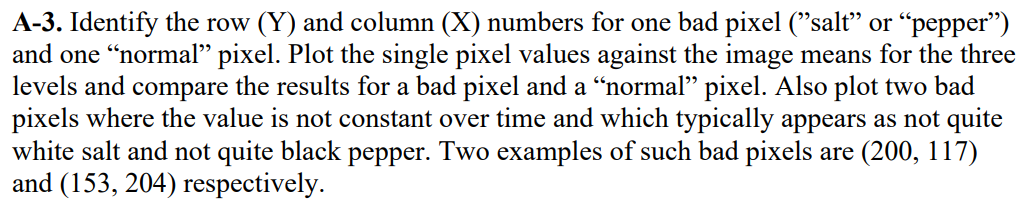 

disp 'a-3'

a-3


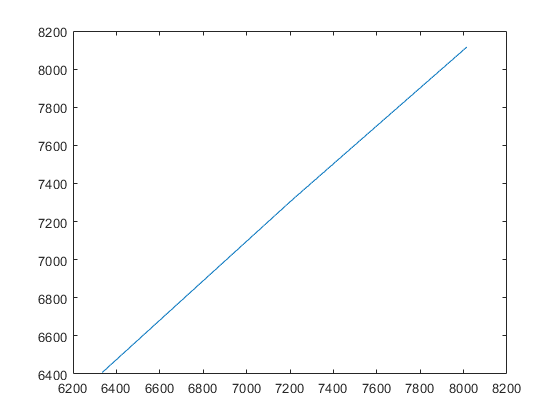

%normal pixel
figure
plot([Refdata1(259,196,1) Refdata2(259,196,1) Refdata3(259,196,1)],m123)

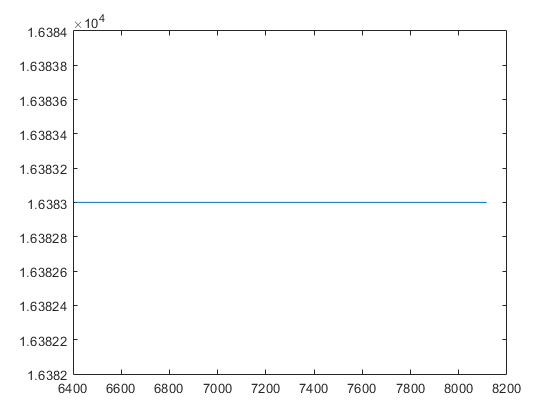

%salt
figure
plot(m123,[Refdata1(113,133,1) Refdata2(113,133,1) Refdata3(113,133,1)])

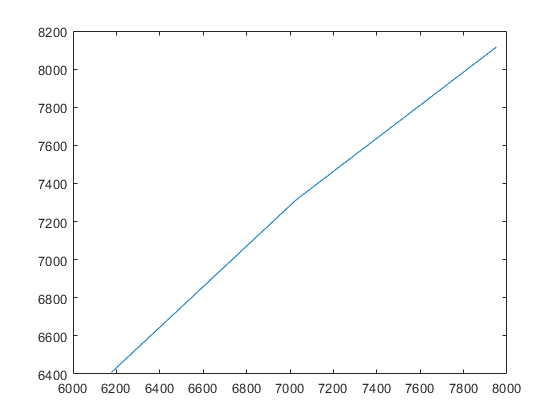

%pepper
figure
plot([Refdata1(216,246,1) Refdata2(216,246,1) Refdata3(216,246,1)],m123)

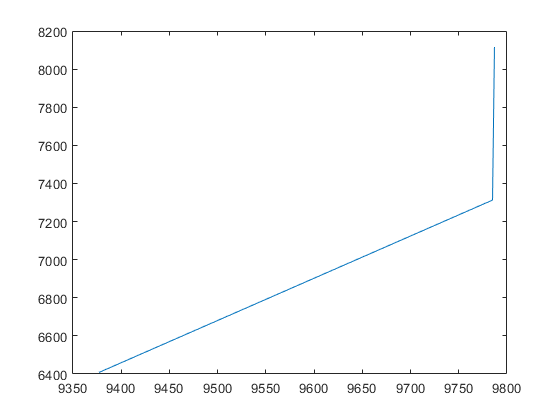

%bad pixel
figure
plot([Refdata1(200,117,1) Refdata2(200,117,1) Refdata3(200,117,1)],m123)

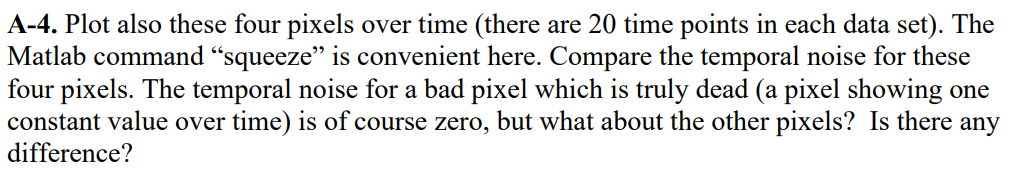

disp 'a_4'

a_4


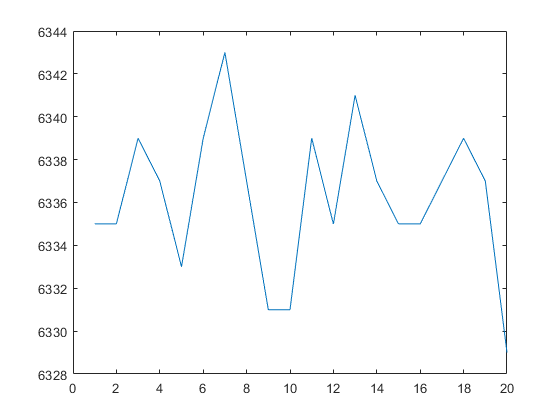

%normal pixel
pix_time = squeeze(Refdata1(259,196,:));
figure
plot(1:20, pix_time)

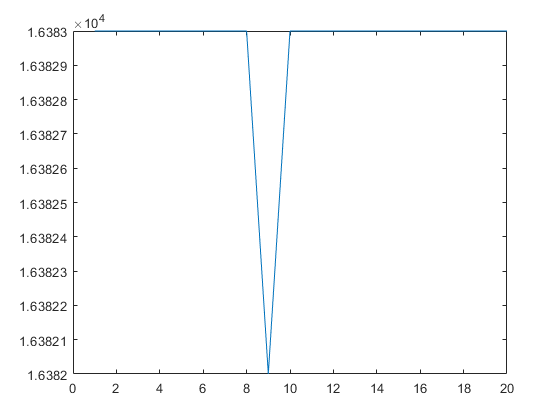


%salt pixel
salt_pix_time = squeeze(Refdata1(113,133,:));
figure
plot(1:20, salt_pix_time)

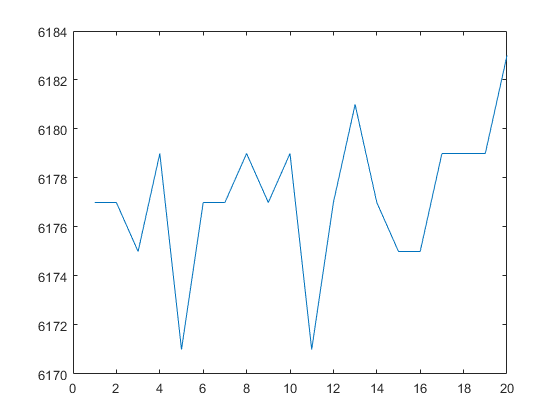


%pepper pixel
pep_pix_time = squeeze(Refdata1(216,246,:));
figure
plot(1:20, pep_pix_time)

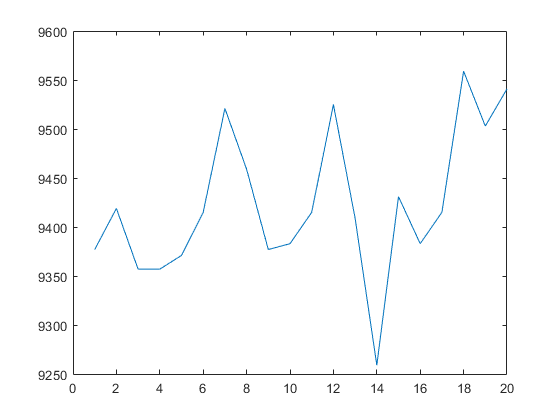


%bad pixel
bad_pix_time = squeeze(Refdata1(200,117,:));
figure
plot(1:20, bad_pix_time)

The salt pixel has a very small dip at time 9 but otherwise constant. The normal pixel varies slightly over time, as well as the pepper pixel but the bad pixel varies quite vastly over time.

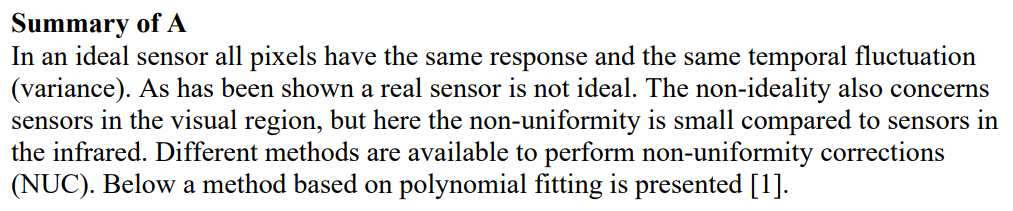

### B. Reference based NUC 

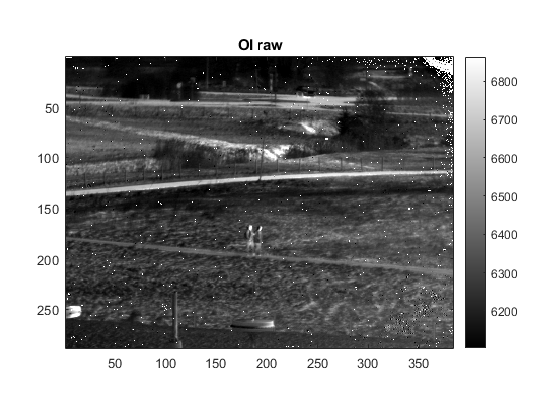

figure
OI_raw=Scenedata(:,:,1);
low_high=stretchlim(OI_raw/16383);
imagesc(OI_raw,[low_high(1) low_high(2)]*16383)
axis image; colormap gray; title('OI raw'); colorbar

clear part low_high 

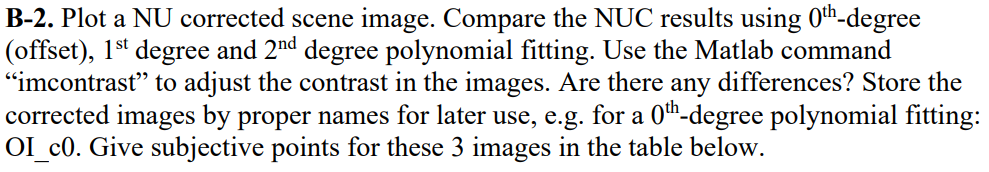

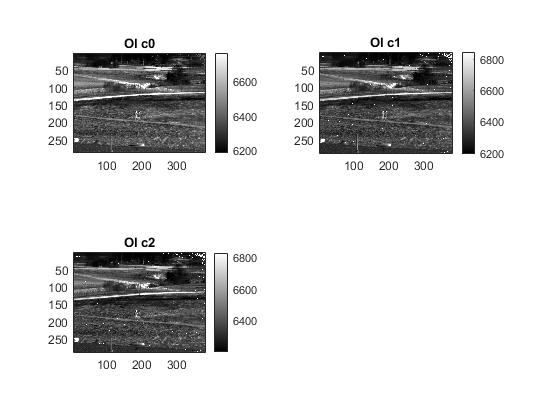

figure

subplot(2,2,1)
OI_c0 = part3_B2(0,Scenedata,Refdata1,Refdata2,Refdata3);

subplot(2,2,2)
OI_c1 = part3_B2(1,Scenedata,Refdata1,Refdata2,Refdata3);

subplot(2,2,3)
OI_c2 = part3_B2(2,Scenedata,Refdata1,Refdata2,Refdata3);

0th degree seems to not show the salt and pepper effects although they are still noise, just not black or white. 2nd degree polynomial fitting has the most accentuated salt and pepper noise.

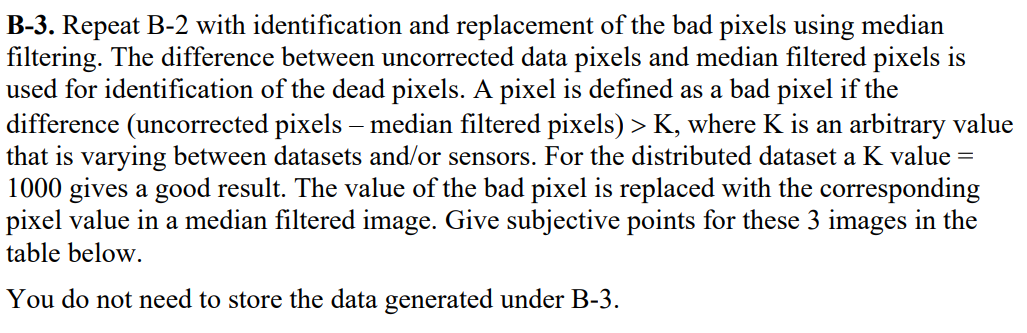

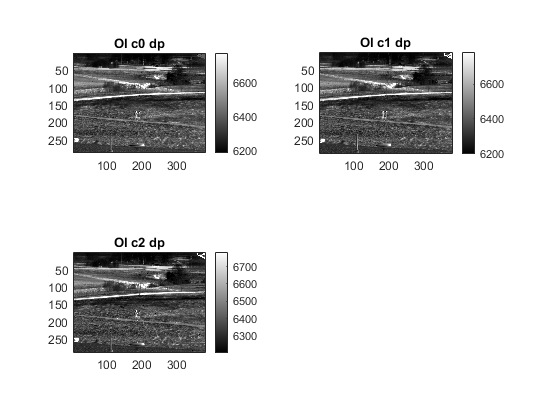

figure

subplot(2,2,1)
OI_c0_dp = part3_B3(0,Scenedata,Refdata1,Refdata2,Refdata3, OI_c0);

subplot(2,2,2)
OI_c1_dp = part3_B3(1,Scenedata,Refdata1,Refdata2,Refdata3, OI_c1);

subplot(2,2,3)
OI_c2_dp = part3_B3(2,Scenedata,Refdata1,Refdata2,Refdata3, OI_c2);

OI_c2_dp is the best.

1

5

2

2

7

7

7

Check for time invariant pixels.

### C. Image quality measures 

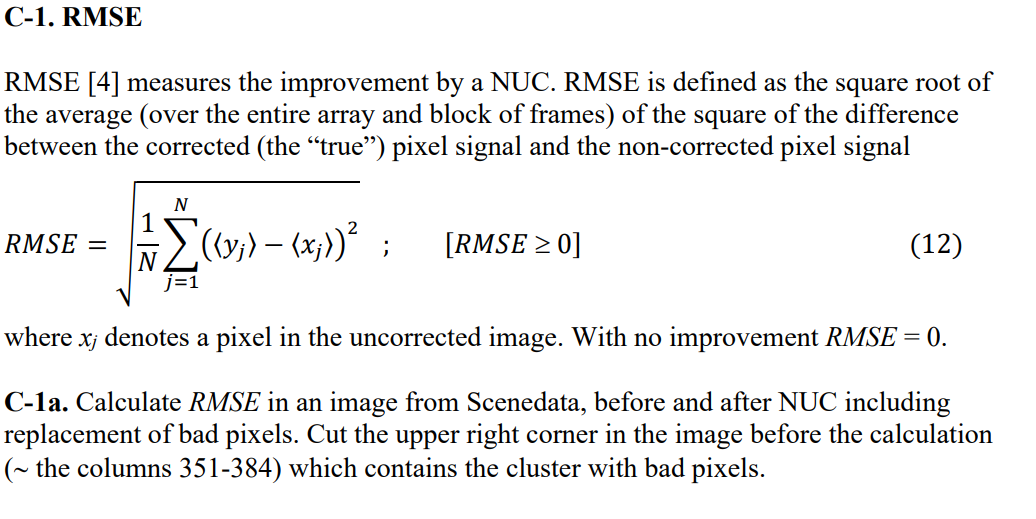  

%here without true dp replacement
RMSE_raw = part3_C1(Scenedata,Scenedata, Refdata1)

RMSE_raw = 0

RMSE_c0 = part3_C1(OI_c0,Scenedata, Refdata1)

RMSE_c0 = 637.8180

RMSE_c1 = part3_C1(OI_c1,Scenedata, Refdata1)

RMSE_c1 = 601.6988

RMSE_c2 = part3_C1(OI_c2,Scenedata, Refdata1)

RMSE_c2 = 604.2493

RMSE_c0dp = part3_C1(OI_c0_dp,Scenedata, Refdata1)

RMSE_c0dp = 643.9305

RMSE_c1dp = part3_C1(OI_c1_dp,Scenedata, Refdata1)

RMSE_c1dp = 645.7302

RMSE_c2dp = part3_C1(OI_c2_dp,Scenedata, Refdata1)

RMSE_c2dp = 650.6153

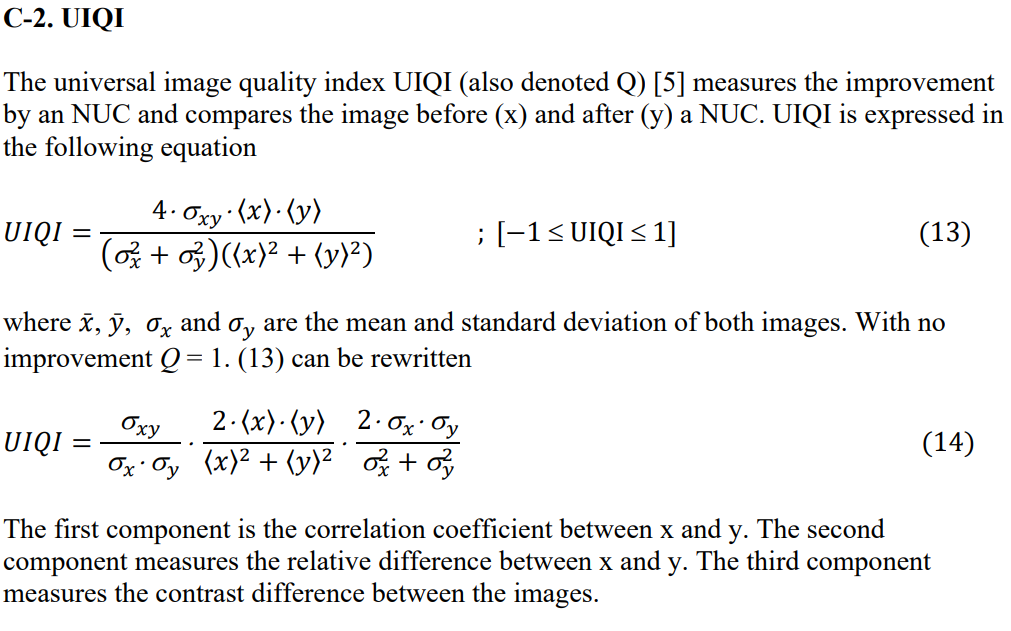

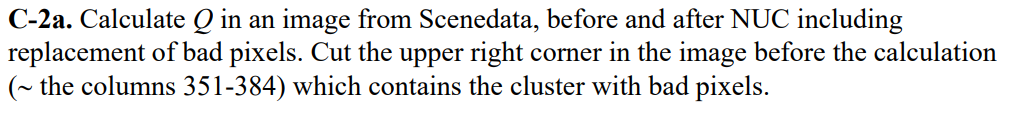

UIQI_raw = part3_C2(Scenedata, Scenedata, Refdata1)

UIQI_raw = 1.0000

UIQI_c0 = part3_C2(OI_c0, Scenedata, Refdata1)

UIQI_c0 = 0.0614

UIQI_c1 = part3_C2(OI_c1, Scenedata, Refdata1)

UIQI_c1 = 0.1931

UIQI_c2 = part3_C2(OI_c2, Scenedata, Refdata1)

UIQI_c2 = 0.1832

UIQI_c0dp = part3_C2(OI_c0_dp, Scenedata, Refdata1)

UIQI_c0dp = 0.0468

UIQI_c1dp = part3_C2(OI_c1_dp, Scenedata, Refdata1)

UIQI_c1dp = 0.0432

UIQI_c2dp = part3_C2(OI_c2_dp, Scenedata, Refdata1)

UIQI_c2dp = 0.0439

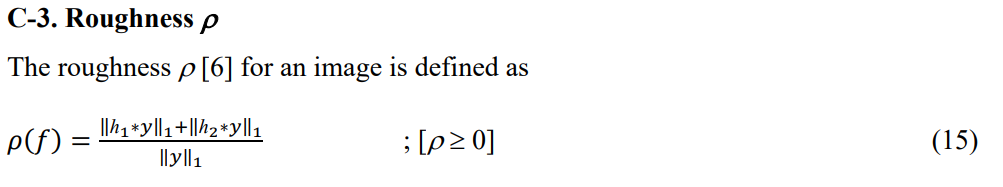

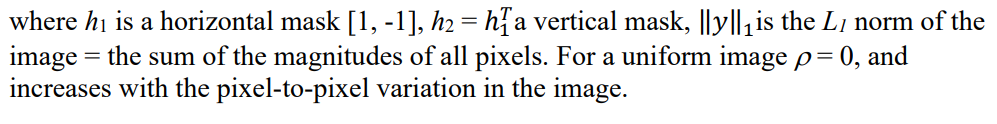

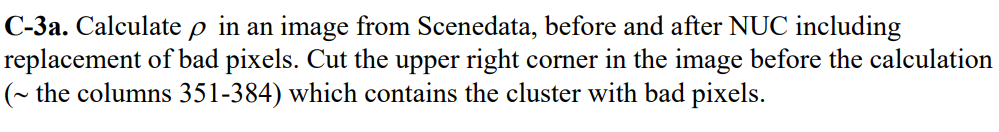

roughness_raw = part3_C3(Scenedata,Scenedata, Refdata1)

roughness_raw = 0.6186

roughness_c0 = part3_C3(OI_c0,Scenedata, Refdata1)

roughness_c0 = 0.0299

roughness_c1 = part3_C3(OI_c1,Scenedata, Refdata1)

roughness_c1 = 0.0694

roughness_c2 = part3_C3(OI_c2,Scenedata, Refdata1)

roughness_c2 = 0.0836

roughness_c0dp = part3_C3(OI_c0_dp,Scenedata, Refdata1)

roughness_c0dp = 0.0344

roughness_c1dp = part3_C3(OI_c1_dp,Scenedata, Refdata1)

roughness_c1dp = 0.0608

roughness_c2dp = part3_C3(OI_c2_dp,Scenedata, Refdata1)

roughness_c2dp = 0.0639

### D. Discussion section B and C 

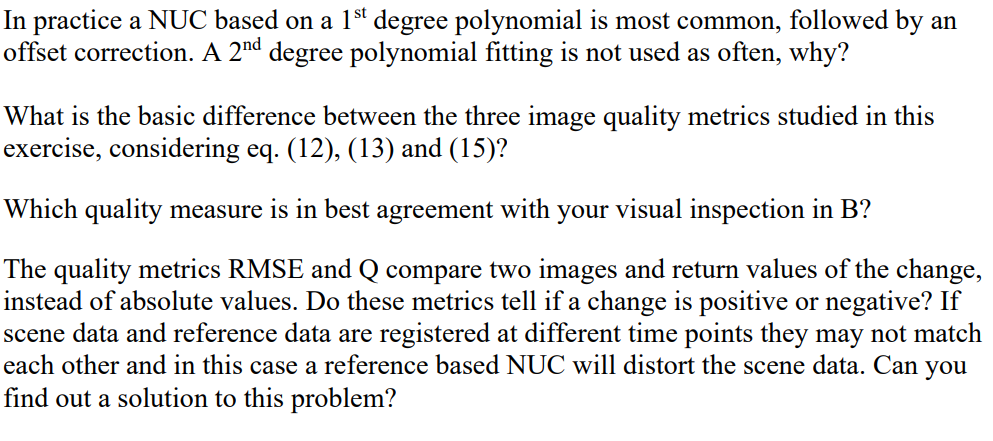

%

A 2nd degree polynomial fitting is very rough and doesn't increase the image quality measure by much. It is also heaver to calculate.

RMSE is calculated from mean square error, UIQI is calculated from correlation and roughness from convolution with two masks compared to the original.

Probably UIQI but more like a combination of all three.

RMSE does not tell if a change is pos or negative but Q can.

If the images are taken at different time instances you could average over multiple images to reduce time variant noise.

%

### E. Comparison with a standard camera

load('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor2 Multiband\Scenedata.mat')


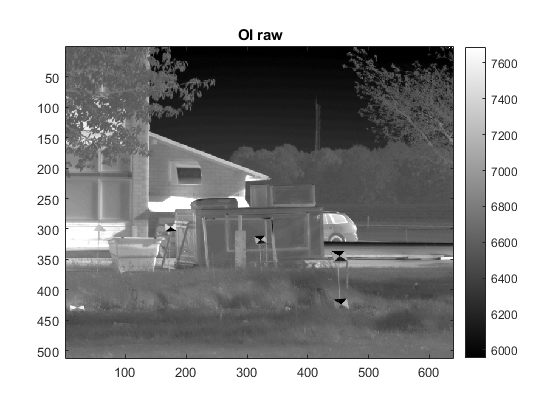

OI_raw=Scenedata(:,:,1);
low_high=stretchlim(OI_raw/16383);
figure(1)
imagesc(OI_raw,[low_high(1) low_high(2)]*16383);
axis image; colormap gray;title('OI raw')
colorbar;

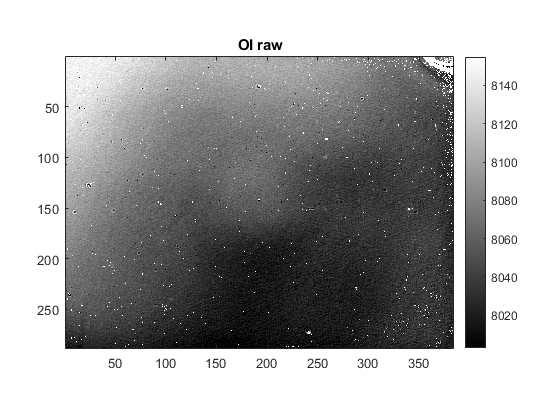

clear part low_high

%compared to
OI_raw=Refdata3(:,:,1);
low_high=stretchlim(OI_raw/16383);
figure(1)
imagesc(OI_raw,[low_high(1) low_high(2)]*16383);
axis image; colormap gray;title('OI raw')
colorbar;

clear part low_high

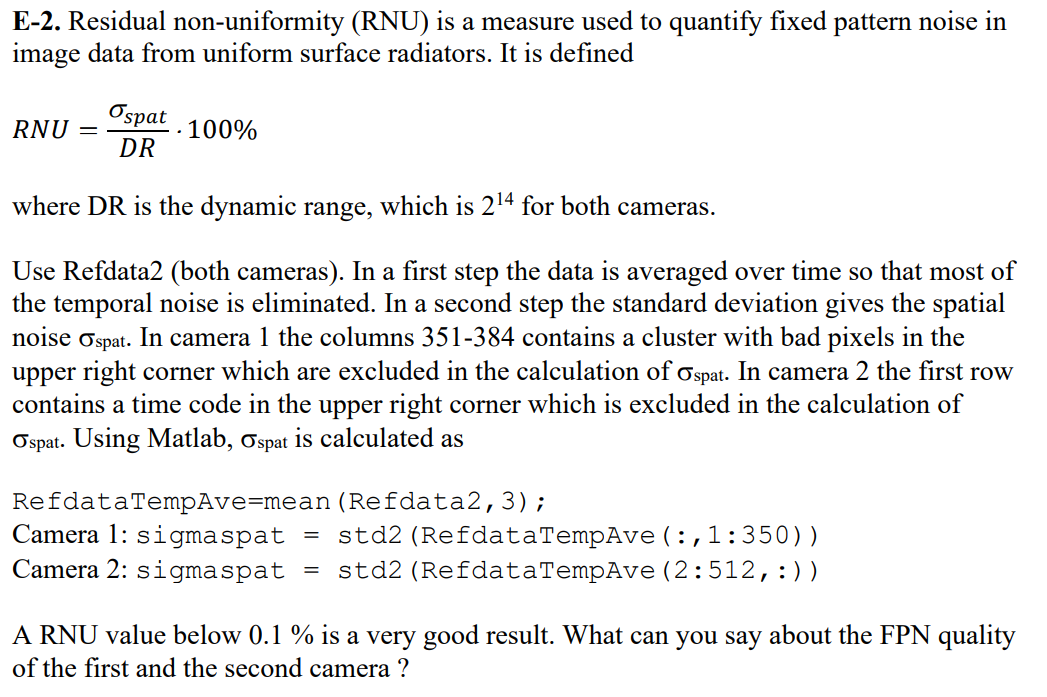

DR = 2^14;
%cam 1
load('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor1 Multispectral\Refdata2.mat')
RefdataTempAve=mean(Refdata2,3);
sigmaspat_1 = std2(RefdataTempAve(:,1:350));
RNU1 = sigmaspat_1/DR*100

RNU1 = 3.5657

%cam 2
load('F:\kurser\master\tsbb09\Lab 4\IRsensors\Sensor2 Multiband\Refdata2.mat')
RefdataTempAve=mean(Refdata2,3);
sigmaspat_2 = std2(RefdataTempAve(2:512,:));
RNU2 = sigmaspat_2/DR*100

RNU2 = 0.0589

Hence camera 1 has more FPN than camera 2.